# Разностные схемы для уравнений эллиптического типа. Итерационные методы решений сеточных уравнений. Вариант 12.

## Условие

Найти решение задачи 


$$Lu = -f (x,y)$$



$$Lu = \frac{\partial }{\partial x}\big((1+\frac{x}{2})\frac{\partial u}{\partial x}\big) + \frac{\partial^2 u}{\partial y^2},\ 0 < x < 1, 0 < y < 1$$



$$u(x,y)\vert_{\Gamma} = \mu(x,y)$$


следующими методами: 

- Методом итерации с оптимальным параметром; 

- Методом Зейделя; 

- Итерационным методом с чебышевским набором параметров; 

- Попеременно-треугольным итерационным методом с чебышевским набором параметров. 

- Методом переменных направлений. 

Отладить решение на функции $u^*(x,y) = xy^2(1+y)$

## Начальные данные

addpath("methods\","norms\","utils\")
global f;
global mu_bot;
global mu_top;
global mu_left;
global mu_right;
global lx;
global ly;
global eps;
global q;
global p;
global pk;
global c1;
global c2;
global d12;
global U_exact;
global k_max;
syms x;
syms y;

lx = 1;
ly = 1;
eps = 0.001;
q = 1;
p = 1 + x/2;
pk = 1;
c1 = 1;
c2 = 1.5;
d12 = 1;
U_exact = x*y^2*(1+y);
[f, mu_bot, mu_top, mu_left, mu_right] = initConditions(U_exact);

N = 10;
M = 10;
k_max = 50;
par = 3;

## Метод итерации с оптимальным параметром

Метод простой итерации с оптимальным параметром:
1. Мера аппроксимации точного решения ||F-Au*||:


norm1 = 3.8475

2. Мера аппроксимации нулевого приближения ||F-Au0||:


norm2 = 395.7255

3. Оценка количества итераций


norm3 = 173

4. Спектральный радиус матрицы перехода:


ro = 0.9607

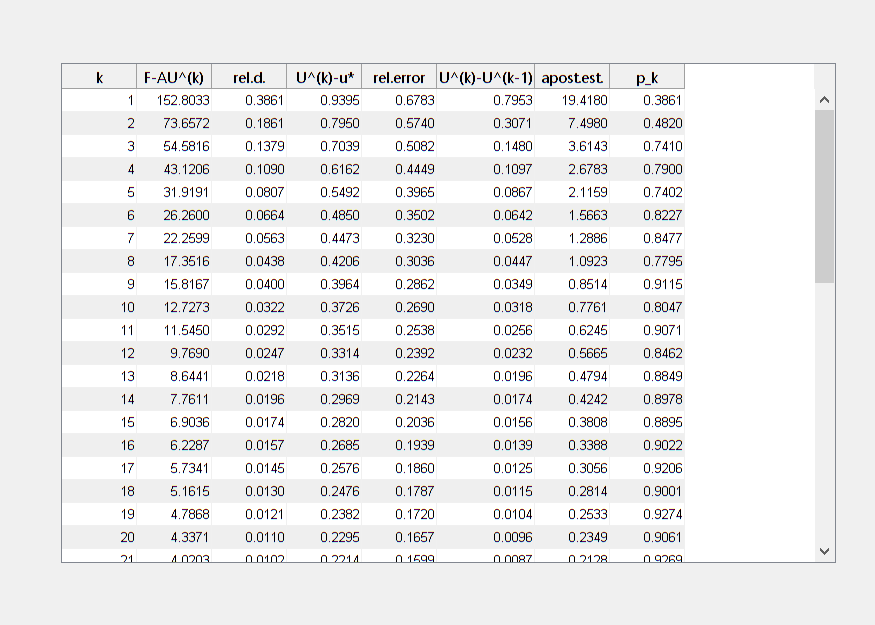

6. Приближенное решение на крупной сетке:


ans =          0         0         0         0         0         0
         0   -0.0183   -0.0218   -0.0100    0.0148    0.0480
         0   -0.0128    0.0067    0.0557    0.1300    0.2240
         0    0.0329    0.1155    0.2359    0.3896    0.5760
         0    0.1497    0.3535    0.5879    0.8502    1.1520
         0    0.4000    0.8000    1.2000    1.6000    2.0000


7. Таблица точного решения на крупной сетке:


ans =          0         0         0         0         0         0
         0    0.0096    0.0192    0.0288    0.0384    0.0480
         0    0.0448    0.0896    0.1344    0.1792    0.2240
         0    0.1152    0.2304    0.3456    0.4608    0.5760
         0    0.2304    0.4608    0.6912    0.9216    1.1520
         0    0.4000    0.8000    1.2000    1.6000    2.0000


u_opt = OptimalSimpleIteration(N, M);

## Метод Зейделя

1. Мера аппроксимации точного решения ||F-Au*||:


norm1 = 3.8475

2. Мера аппроксимации нулевого приближения ||F-Au0||:


norm2 = 395.7255

3. Оценка количества итераций


norm3 = 87

4. Спектральный радиус матрицы перехода:


ro = 0.9229

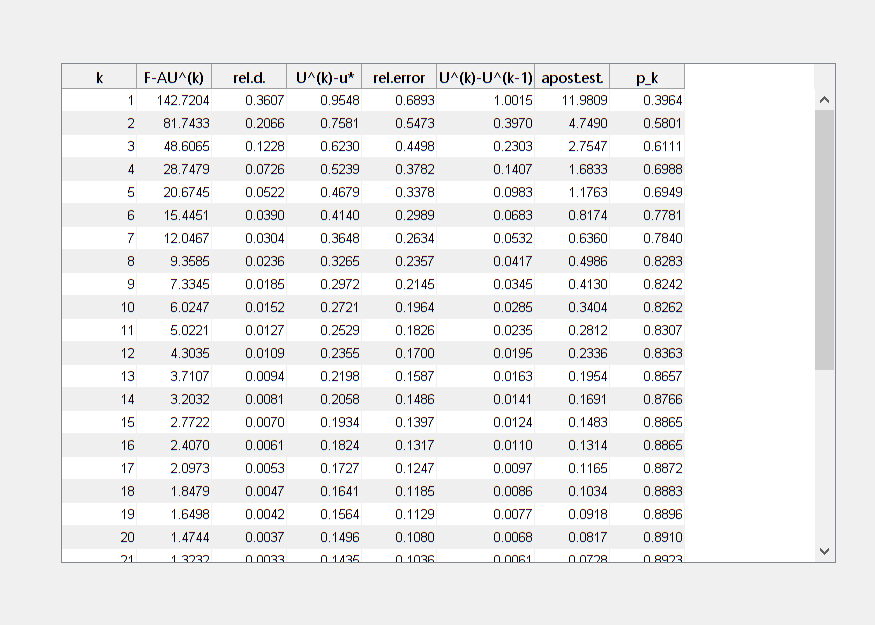

6. Приближенное решение на крупной сетке:


ans =          0         0         0         0         0         0
         0   -0.0153   -0.0165   -0.0043    0.0186    0.0480
         0   -0.0064    0.0176    0.0671    0.1373    0.2240
         0    0.0410    0.1290    0.2497    0.3982    0.5760
         0    0.1556    0.3632    0.5977    0.8563    1.1520
         0    0.4000    0.8000    1.2000    1.6000    2.0000


7. Таблица точного решения на крупной сетке:


ans =          0         0         0         0         0         0
         0    0.0096    0.0192    0.0288    0.0384    0.0480
         0    0.0448    0.0896    0.1344    0.1792    0.2240
         0    0.1152    0.2304    0.3456    0.4608    0.5760
         0    0.2304    0.4608    0.6912    0.9216    1.1520
         0    0.4000    0.8000    1.2000    1.6000    2.0000


 u_zeid = ZeidelMethod(N, M);

## Итерационный метод с чебышевским набором параметров

Метод итераций с оптимальным Чебышевским параметром:
1. Мера аппроксимации точного решения ||F-Au*||:


norm1 = 3.8475

2. Мера аппроксимации нулевого приближения ||F-Au0||:


norm2 = 395.7255

3. Оценка количества итераций


norm3 = 27

4. Спектральный радиус матрицы перехода:


ro = 0.9607

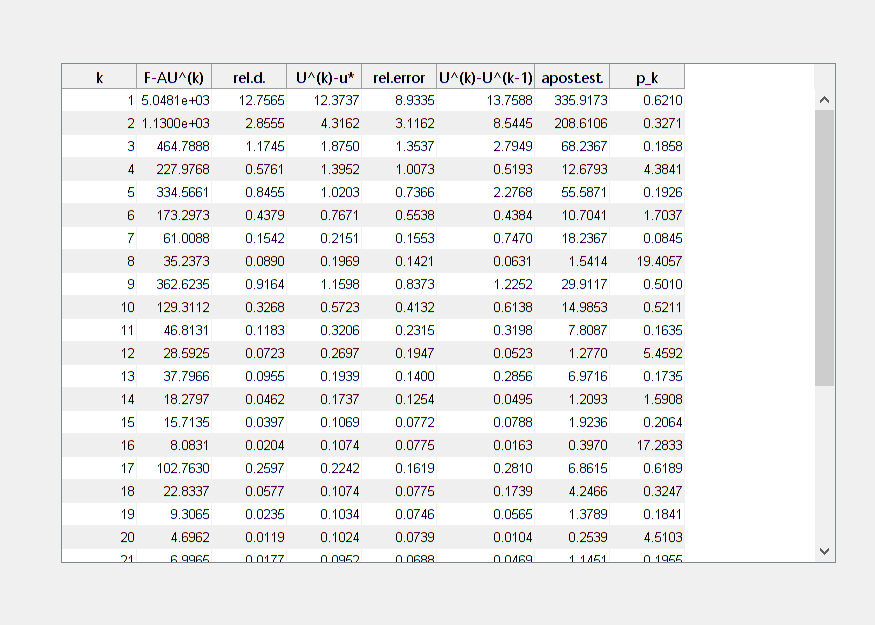

6. Приближенное решение на крупной сетке:


ans =          0         0         0         0         0         0
         0   -0.0101   -0.0091    0.0034    0.0226    0.0480
         0    0.0044    0.0321    0.0790    0.1437    0.2240
         0    0.0505    0.1420    0.2611    0.4039    0.5760
         0    0.1612    0.3708    0.6038    0.8590    1.1520
         0    0.4000    0.8000    1.2000    1.6000    2.0000


7. Таблица точного решения на крупной сетке:


ans =          0         0         0         0         0         0
         0    0.0096    0.0192    0.0288    0.0384    0.0480
         0    0.0448    0.0896    0.1344    0.1792    0.2240
         0    0.1152    0.2304    0.3456    0.4608    0.5760
         0    0.2304    0.4608    0.6912    0.9216    1.1520
         0    0.4000    0.8000    1.2000    1.6000    2.0000


 u_cheb = ChebIterationMethods(N, M, par);

## Попеременно-треугольный итерационный метод с чебышевским набором параметров.

Поперемено-треугольный метод с оптимальными чебышевскими параметрами:
1. Мера аппроксимации точного решения ||F-Au*||:


norm1 = 3.8475

2. Мера аппроксимации нулевого приближения ||F-Au0||:


norm2 = 395.7255

3. Оценка количества итераций
Считаем отдельно.
4. Спектральный радиус матрицы перехода:


ro = 0.6058

3. Оценка количества итераций


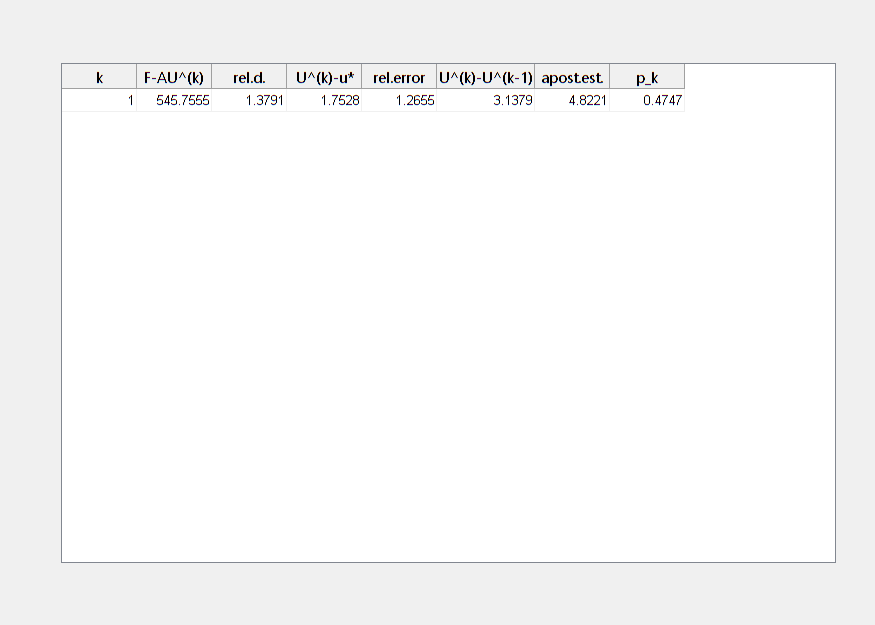

6. Приближенное решение на крупной сетке:


ans =          0         0         0         0         0         0
         0   -0.0035   -0.0096   -0.0047    0.0175    0.0480
         0    0.0062    0.0393    0.0896    0.1609    0.2240
         0    0.0452    0.1844    0.3537    0.5257    0.5760
         0    0.1361    0.4195    0.7605    1.1414    1.1520
         0    0.4000    0.8000    1.2000    1.6000    2.0000


7. Таблица точного решения на крупной сетке:


ans =          0         0         0         0         0         0
         0    0.0096    0.0192    0.0288    0.0384    0.0480
         0    0.0448    0.0896    0.1344    0.1792    0.2240
         0    0.1152    0.2304    0.3456    0.4608    0.5760
         0    0.2304    0.4608    0.6912    0.9216    1.1520
         0    0.4000    0.8000    1.2000    1.6000    2.0000


 AlternateTriangularMethod(N, M, par);   

## Метод переменных направлений

Схема переменных направлений:
1. Мера аппроксимации точного решения ||F-Au*||:


norm1 = 3.8475

2. Мера аппроксимации нулевого приближения ||F-Au0||:


norm2 = 395.7255

3. Оценка количества итераций


norm3 = 11

4. Спектральный радиус матрицы перехода:
-


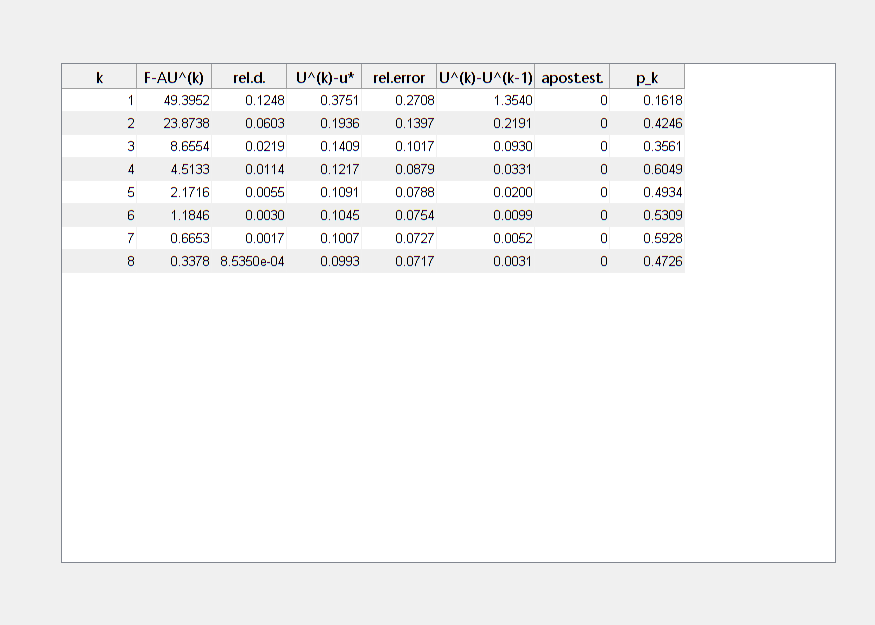

6. Приближенное решение на крупной сетке:


ans =          0         0         0         0         0         0
         0   -0.0092   -0.0079    0.0032    0.0223    0.0480
         0    0.0027    0.0303    0.0781    0.1428    0.2240
         0    0.0493    0.1405    0.2597    0.4032    0.5760
         0    0.1602    0.3696    0.6031    0.8589    1.1520
         0    0.4000    0.8000    1.2000    1.6000    2.0000


7. Таблица точного решения на крупной сетке:


ans =          0         0         0         0         0         0
         0    0.0096    0.0192    0.0288    0.0384    0.0480
         0    0.0448    0.0896    0.1344    0.1792    0.2240
         0    0.1152    0.2304    0.3456    0.4608    0.5760
         0    0.2304    0.4608    0.6912    0.9216    1.1520
         0    0.4000    0.8000    1.2000    1.6000    2.0000


 u_dir_var = DirectionVariablesMethod(N, M);